# Project MSB1015: Ayahuasca

## Script 5: PCA

## Guus Wilmink, i6156211

## Load data

clear all; close all;

% Add Fieldtrip toolbox
addpath('./fieldtrip-20220912');

% Load the data
load('.\processed_1_30Hz.mat');
load('.\processed_30_100Hz.mat');
elec = load(".\freqs_1-30Hz.mat").data_all_mean.elec;

% Specify bands
delta=2.5; theta=6; alpha=10.5; beta=21.5; slowgamma=40; fastgamma=75;

**Select frequency band or all frequencies**

band = alpha;       % Frequency band

% Prepare data
if length(band) == 1
    data = zeros(6,16,63);
elseif length(band) == 30
    data = zeros(6,16,63,30);
else
    data = zeros(6,16,63,15);
end
for trial = 1:6
    if band == delta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,1));
    end
    if band == theta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,2));
    end
    if band == alpha
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,3));
    end
    if band == beta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,4));
    end
    if band == slowgamma
        data(trial,:,:) = squeeze(processed_30_100Hz{trial}.powspctrm_b(:,:,1));
    end
    if band == fastgamma
        data(trial,:,:) = squeeze(processed_30_100Hz{trial}.powspctrm_b(:,:,2));
    end
end

## PCA for subject-trial pairs

Single plot with all trials of all subjects

Fistly the matrices are combined and transformed, so each row represents a subject-trial pair and each column a channel. Row 1-16 will be subject 1-16, trial 1; row 17-36 will be subject 1-16, trial 2; etc..

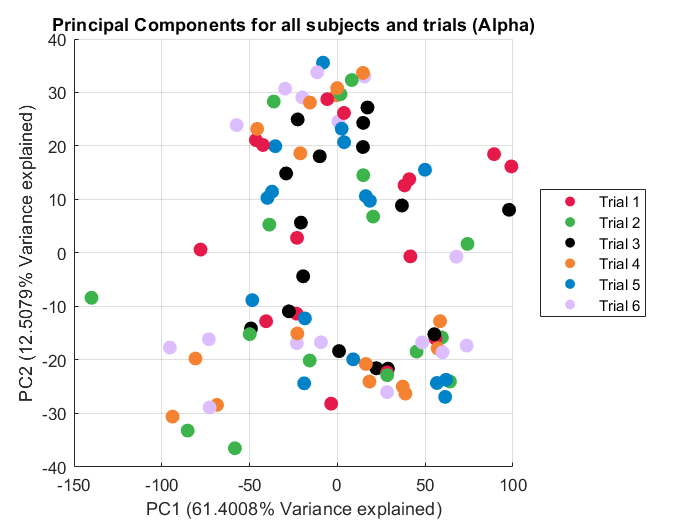

col_selection = "trials";

% Mean centre data
MC_data = zeros(6, 16, 63);
for subj = 1:16
    for chan = 1:63
        temp                 = squeeze(data(:,subj,chan));
        mu                   = mean(temp);
        temp                 = temp - mu;
        MC_data(:,subj,chan) = temp-mu;
    end
end

% Transform matrices into single matrix
transformed_data = zeros(96, 63);
for trial=1:6
    transformed_data((1+16*trial-16):(16*trial),:) = squeeze(data(trial,:,:));
end



if col_selection == 'trials'
    % Set colors
    colors = [230 25 75; 60 180 75; 0 0 0; 245 130 48; 0 130 200; 220 190 255];
    colors = colors./255;
    colors = repmat(colors, 16, 1);

    % Compute PCAs
    [coeff,score,latent,tsquared,explained,mu] = pca(transformed_data);
    rpt_subj_PCA.coeff                         = coeff;
    rpt_subj_PCA.score                         = score;
    rpt_subj_PCA.latent                        = latent;
    rpt_subj_PCA.tsquared                      = tsquared;
    rpt_subj_PCA.explained                     = explained;
    rpt_subj_PCA.mu                            = mu;

    % Dummy plotting for legend handles
    figure; hold on;
    for trial = 1:6
        scatter(rpt_subj_PCA.score(trial, 1), rpt_subj_PCA.score(trial, 2), 50, colors(trial,:), 'filled')
    end


    % Plot PCAs
    for rpt_subj=1:96
        trial = 1;
        if rpt_subj > 16
            trial = 2;
            if rpt_subj > 32
                trial = 3;
                if rpt_subj > 48
                    trial = 4;
                    if rpt_subj > 64
                        trial = 5;
                        if rpt_subj > 80
                            trial = 6;
                        end
                    end
                end
            end
        end
        %     scatter(rpt_subj_PCA.score(rpt_subj,1), rpt_subj_PCA.score(rpt_subj,2), sizes(trial), colors(rpt_subj,:), markers{trial}, 'filled')
        scatter(rpt_subj_PCA.score(rpt_subj,1), rpt_subj_PCA.score(rpt_subj,2), 70, colors(rpt_subj,:), 'filled')
    end
    grid on
    % legend('Subject 1', 'Subject 2', 'Subject 3', 'Subject 4', 'Subject 5', 'Subject 6', 'Subject 7', 'Subject 8', 'Subject 9', 'Subject 10',  'Subject 11', 'Subject 12', 'Subject 13', 'Subject 14', 'Subject 15', 'Subject 16', 'Trial baseline', 'Trial 2', 'Trial 3', 'Trial 4', 'Trial 5', 'Trial 6', 'Location', 'Eastoutside')
    legend('Trial 1', 'Trial 2', 'Trial 3', 'Trial 4', 'Trial 5', 'Trial 6', 'Location', 'EastOutside')
    xlabel(['PC1 (' num2str(rpt_subj_PCA.explained(1)) '% Variance explained)'])
    ylabel(['PC2 (' num2str(rpt_subj_PCA.explained(2)) '% Variance explained)'])
    if band == delta
        title('Principal Components for all subjects and trials (Delta)')
    elseif band == theta
        title('Principal Components for all subjects and trials (Theta)')
    elseif band == alpha
        title('Principal Components for all subjects and trials (Alpha)')
    elseif band == beta
        title('Principal Components for all subjects and trials (Beta)')
    elseif band == slowgamma
        title('Principal Components for all subjects and trials (Slow Gamma)')
    elseif band == fastgamma
        title('Principal Components for all subjects and trials (Fast Gamma)')
    end
else 
    % Set colors
    colors = repmat(col, 6, 1);

    % Compute PCAs
    [coeff,score,latent,tsquared,explained,mu] = pca(transformed_data);
    rpt_subj_PCA.coeff                         = coeff;
    rpt_subj_PCA.score                         = score;
    rpt_subj_PCA.latent                        = latent;
    rpt_subj_PCA.tsquared                      = tsquared;
    rpt_subj_PCA.explained                     = explained;
    rpt_subj_PCA.mu                            = mu;

    % Dummy plotting for legend handles
    figure; hold on;
    for subj = 1:16
        scatter(rpt_subj_PCA.score(subj,1), rpt_subj_PCA.score(subj,2), 50, colors(subj,:), 'filled')
    end
    scatter(rpt_subj_PCA.score(1,1), rpt_subj_PCA.score(1,2), 'k', markers{1}, 'filled')
    scatter(rpt_subj_PCA.score(2,1), rpt_subj_PCA.score(2,2), 'k', markers{2}, 'filled')
    scatter(rpt_subj_PCA.score(3,2), rpt_subj_PCA.score(3,2), 'k', markers{3}, 'filled')
    scatter(rpt_subj_PCA.score(4,1), rpt_subj_PCA.score(4,2), 'k', markers{4}, 'filled')
    scatter(rpt_subj_PCA.score(5,1), rpt_subj_PCA.score(5,2), 'k', markers{5}, 'filled')
    scatter(rpt_subj_PCA.score(6,2), rpt_subj_PCA.score(6,2), 'k', markers{6}, 'filled')
    for trial = 1:6
        scatter(rpt_subj_PCA.score(trial, 1), rpt_subj_PCA.score(trial, 2), 50, colors(trial,:), 'filled')
    end


    % Plot PCAs
    for rpt_subj=1:96
        trial = 1;
        if rpt_subj > 16
            trial = 2;
            if rpt_subj > 32
                trial = 3;
                if rpt_subj > 48
                    trial = 4;
                    if rpt_subj > 64
                        trial = 5;
                        if rpt_subj > 80
                            trial = 6;
                        end
                    end
                end
            end
        end
        scatter(rpt_subj_PCA.score(rpt_subj,1), rpt_subj_PCA.score(rpt_subj,2), 50, colors(rpt_subj,:), 'o', 'filled')
    end
    grid on
    legend('Subject 1', 'Subject 2', 'Subject 3', 'Subject 4', 'Subject 5', 'Subject 6', 'Subject 7', 'Subject 8', 'Subject 9', 'Subject 10',  'Subject 11', 'Subject 12', 'Subject 13', 'Subject 14', 'Subject 15', 'Subject 16', 'Location', 'Eastoutside');
    xlabel(['PC1 (' num2str(rpt_subj_PCA.explained(1)) '% Variance explained)'])
    ylabel(['PC2 (' num2str(rpt_subj_PCA.explained(2)) '% Variance explained)'])
    if band == delta
        title('Principal Components for all subjects and trials (Delta)')
    elseif band == theta
        title('Principal Components for all subjects and trials (Theta)')
    elseif band == alpha
        title('Principal Components for all subjects and trials (Alpha)')
    elseif band == beta
        title('Principal Components for all subjects and trials (Beta)')
    elseif band == slowgamma
        title('Principal Components for all subjects and trials (Slow Gamma)')
    elseif band == fastgamma
        title('Principal Components for all subjects and trials (Fast Gamma)')
    end
end